# WIFI Transmitter

#### History

- 2024-09-18, Draft

- 2024-09-19, Release V1.0

- 2024-09-25, Release V2.0, Apply CFR 

#### Set WIFI line-up

% close all
% clear all
% clc
format shortG

simulation_trx = 'tx' % set Tx case

simulation_trx = 'tx'

switch simulation_trx
    case {'tx','trx'}
        paModel_LUT_sheet = '0527SIMCW'  % set LUT sheet
        paModel_methology = 'RFSIMPA' % set pa model function
        PaModel_type = 'LUT'
        isMultiStage = 0
        isPaFlatness = 0
        isMIMO = 0
end

paModel_LUT_sheet = '0527SIMCW'

paModel_methology = 'RFSIMPA'

PaModel_type = 'LUT'

isMultiStage =      0


isPaFlatness =      0


isMIMO =      0



if 1 % set spec. using competitors
    competitorsCase = 'ICWF5519' % iC
    % competitorsCase = 'KCT8570HE' % KCT8570HE
    % competitorsCase = 'SKY85797.11'
    % competitorsCase = 'OTHERS'
end

competitorsCase = 'ICWF5519'


switch competitorsCase
    case "ICWF5519"
        signalFormat_vec = ["EHT160","HE160","HE160","VHT80","HT40","HT20"];
        signalFormat_vec = ["EHT160","HE160","HE160","VHT80","HT40","HT20"]; % test
        MCS_index_vec = [13 11 11 9 7 0];
        MCS_index_vec = [13 11 11 9 7 0]; % test
        paOutputPower_target_dBm_vec = [15 16 18 23 24 27] + 0.8;
        % paOutputPower_target_dBm_vec = [15 16 18 23 24 27] + 0.8; % test
        specEVM_vec = [-47 -43 -43 -35 -30 nan];
    case "ICWF5971"
        signalFormat_vec = ["EHT320","HE160","VHT80","HT40","HT20"];
        MCS_index_vec = [13 11 9 7 0];
        paOutputPower_target_dBm_vec = [15 18 23 24 27] + 0.8;
        specEVM_vec = [-47 -43 -35 -30 nan];
    case "QPF4702"
        signalFormat_vec = ["EHT320","HE160","VHT80","HT40","HT20"];
        MCS_index_vec = [13 11 9 7 0];
        paOutputPower_target_dBm_vec = [18 21 24 24 27] + 0;
        specEVM_vec = [-47 -43 -35 -30 nan];
    case "KCT8570N"
        signalFormat_vec = ["EHT160","HE160","VHT80","HT40","HT20"];
        MCS_index_vec = [13 11 9 7 0];
        paOutputPower_target_dBm_vec = [21.5 22.5 24 25 27] + 0;
        specEVM_vec = [-47 -43 -35 -30 nan];
    otherwise % user-defined
        signalFormat_vec = [...
            "EHT20","EHT40","EHT80","EHT160","EHT320";...
            % "EHT320"
            ];
        MCS_index_vec = [...
            % 0 0 0 0 0;...
            % 1 1 1 1 1;...
            % 2 2 2 2 2;...
            % 3 3 3 3 3;...
            % 4 4 4 4 4;...
            % 5 5 5 5 5;...
            % 6 6 6 6 6;...
            % 7 7 7 7 7;...
            % 8 8 8 8 8;...
            % 9 9 9 9 9;...
            % 10 10 10 10 10;...
            % 11 11 11 11 11;...
            % 12 12 12 12 12;...
            13 13 13 13 13;...
            % 13
            ];
        paOutputPower_target_dBm_vec = [...
            25 24 22.5 21.5 20.5...
            % 20.5
            ];
end


if size(signalFormat_vec,1)~=size(MCS_index_vec,1) % check
    error('!')
end


#### Set Waveform Configurations

try
    k
catch
    k=6;
end

k =      5


if 1 % initialization
    clear wv
    signalFormat = signalFormat_vec(k)
    MCS_index = MCS_index_vec(k)
    paOutputPower_target_dBm = paOutputPower_target_dBm_vec(k)
    dispLegd_format = ("MCS"+string(MCS_index)+"."+signalFormat);
    specEVM = specEVM_vec(k)
end

signalFormat = "HT40"

MCS_index =      7


paOutputPower_target_dBm =          24.8


specEVM =    -30



% set wv configurations
configParamsWG                  = struct();
configParamsWG.wlanPHY          = erase(signalFormat, ["20","40","80","160","320"]);
configParamsWG.bw               = erase(signalFormat, ["HT","VHT","EHT","HE"])+"MHz";
configParamsWG.NumUsers         = 1; % set wv MIMO number of users
configParamsWG.MCS              = MCS_index;
if isMIMO
    configParamsWG.NumSpaceTimeStreams  = 2;        %[1 1];
    configParamsWG.NumTransmitAntennas  = 2;        %2;
else
    configParamsWG.NumSpaceTimeStreams  = 1;        %[1 1];
    configParamsWG.NumTransmitAntennas  = 1;        %2;
end
configParamsWG.APEPLength       = 2048/1;       % 8x and APEPLength <= PSDU Length
configParamsWG.save_tvs         = 0;            % if 1, output files as stored
configParamsWG.show_figs        = 0;
configParamsWG.windowingRatio   = 0;
configParamsWG.bbFilter_en      = 1;
configParamsWG.bbFilterSbAtten  = 112;
configParamsWG.resampleFilterN  = 20*4;         % increase this parameter to sharpen resample filter transition band (improve ACLR of ideal waveform)
configParamsWG.resampleFilterB  = 13.5;
configParamsWG.outputLevelDbfs  = -15;
configParamsWG.outputSampleRate = [];
configParamsWG.floatPoint_en    = 0;

if 1 % set wv guard interval
    configParamsWG.GuardInterval = 0.8;
    disp('2024-04-17, If GuardInterval < 3.2us, the bbFilter significatly affects the band edge response and EVM')
    % configParamsWG.bbFilter_en = 0;5
else
    configParamsWG.GuardInterval = 3.2;
end

2024-04-17, If GuardInterval < 3.2us, the bbFilter significatly affects the band edge response and EVM



if strcmpi(signalFormat, 'HT20')
    configParamsWG.bbFilter_en = 1;
end

if 0 % set over sampling ratio
    configParamsWG.osr = [];
else
    configParamsWG.osr = 4;
    % configParamsWG.osr = 6;
    % configParamsWG.osr = 8;
    % configParamsWG.osr = 10;
end


if strcmpi(simulation_trx, 'rx') && isAdjacentChannelRejection_sim
    configParamsWG.osr = 4;
end

if 1
    configParamsWG.resampleFilter_method = 'waveformGen';
    configParamsWG.resampleFilter_en = 0;
else
    configParamsWG.resampleFilter_method = 'resampleFun'; % bad
    configParamsWG.resampleFilter_en = 1;
end

if 0 % set wv number of packets and
    configParamsWG.NumPackets = 10;
else
    configParamsWG.NumPackets = 4;
end


if 1*0 % set wv idle time
    disp('If IdleTime = 40us, papr is higher but less noise ?')
    configParamsWG.IdleTime = 40e-6;
elseif 2*0
    disp('If IdleTime = 5us, papr is lower but more noise ?')
    configParamsWG.IdleTime = 5e-6;
else
    configParamsWG.IdleTime = 10e-6; % user-defined
end

if 0 % save waveform
    configParamsWG.save_tvs = 1;
    configParamsWG.fileFormat = "TXT_ADS";
    configParamsWG.wlanBand = "5GHz";
    configParamsWG.note = "";
end


#### Generate Waveform and set 

% get wv configurations
configWG = ovwrConfig(waveformGenWLAN,configParamsWG);

% get wv parameters
passParams = waveformGenWLAN.runWG(configWG);

bbFilter: filter bw tolerance 2.0MHz



% export wv
wv = passParams.finalSignal;
fs = passParams.outputSampleRate;
fsMHz = fs / 1e6;
cfg = passParams.cfgFormat;
dlSlots = passParams.usefulWvfm;
cbw = passParams.currentBw;

% set transmitter power
wv = powerDbm(wv,'set',paOutputPower_target_dBm,'dBm',dlSlots);
transmitPwr_dBm = powerDbm(wv,'rms',[],'dBm',dlSlots);

if 1 % store original wv
    wv_org = wv;
    wv = wv_org;
end

if 1 % initialize PLOT_WLAN
    rbwKHz = 10 % set plt rbwKHz
    pltWlan = PLOT_WLAN(cfg);
    pltWlan.RbwKHz = rbwKHz;
    pltComm = PLOT_COMM([], [], fsMHz, rbwKHz);
end

rbwKHz =     10


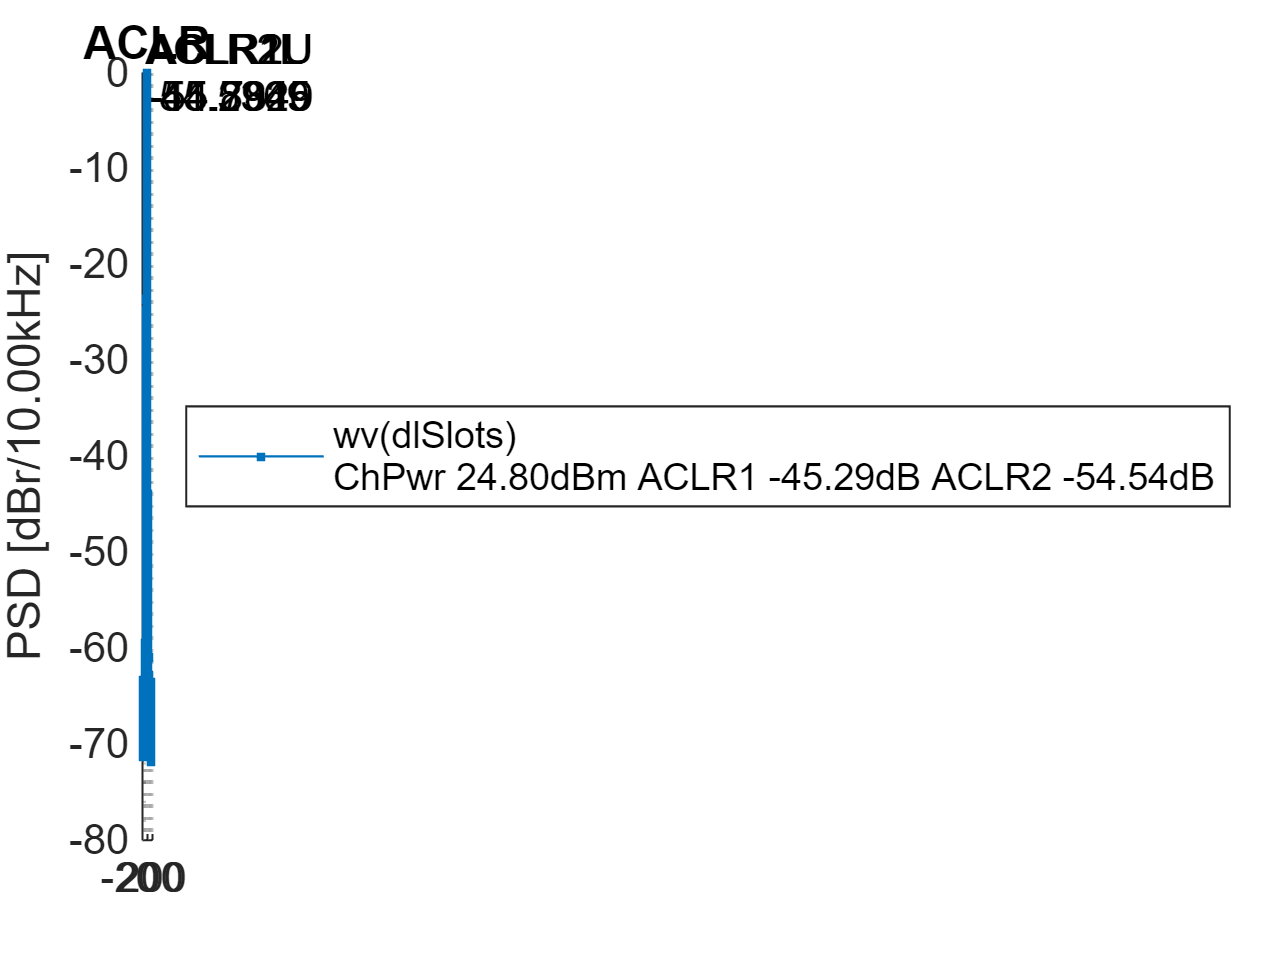

aclrVal_wv = struct with fields:
                       nCC: 1
                      isCA: 0
                       OSR: 2
           ChannelPowerDbm: 24.802
                    ACLRdB: [-54.537 -45.295 -45.893 -54.785]
                      Plot: [1×1 struct]
              CarrierBwMHz: 38
              ChannelBwMHz: 40
         ChannelOffset0MHz: 0
                 AclrBwMHz: 200
                    ScsKHz: 10
             SampleRateMHz: 160
         OverSampleRateMHz: 320
            CarrierFreqMHz: 0
    AdjacentChannelFreqMHz: [-80 -40 40 80]
                      Unit: "MHz"
               Description: "wv(dlSlots)"
                     ACLR1: -45.295
                     ACLR2: -54.537


ans = struct with fields:
                  nCC: 1
                 isCA: 0
                  OSR: 1
                 Plot: [1×1 struct]
         CarrierBwMHz: []
         ChannelBwMHz: []
    ChannelOffset0MHz: 0
            AclrBwMHz: 160
               ScsKHz: 10
        SampleRateMHz: 160
    OverSampleRateMHz: 160
                 Unit: "MHz"
          Description: "wv(dlSlots)"


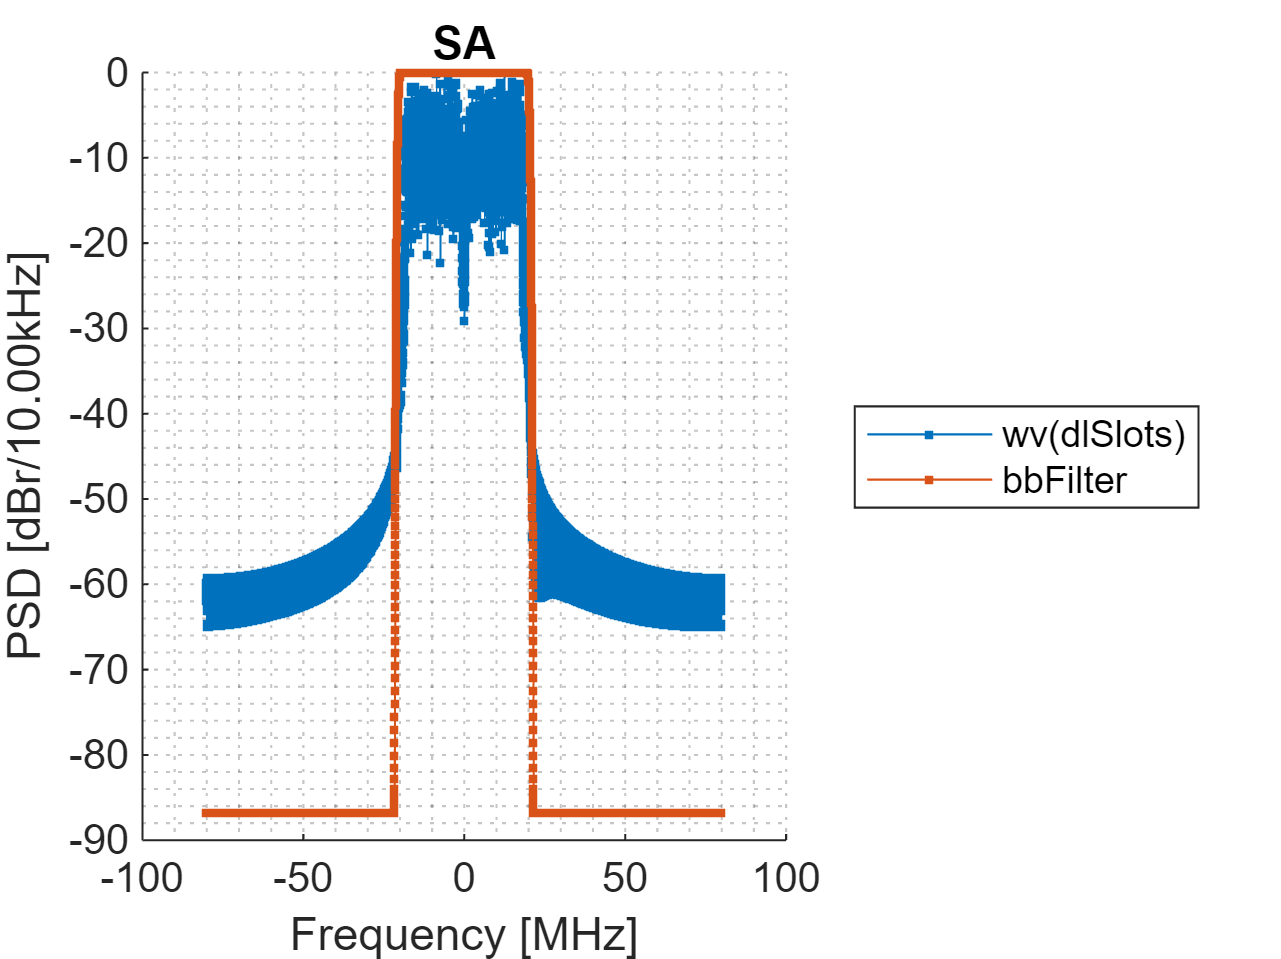

ans = struct with fields:
                  nCC: 1
                 isCA: 0
                  OSR: 1
                 Plot: [1×1 struct]
         CarrierBwMHz: []
         ChannelBwMHz: []
    ChannelOffset0MHz: 0
            AclrBwMHz: 160
               ScsKHz: 10
        SampleRateMHz: 160
    OverSampleRateMHz: 160
                 Unit: "MHz"
          Description: "bbFilter"



if 1 % plot wv aclr / filter sa
    aclrVal_wv = pltWlan.aclr(pltWlan, wv(dlSlots), [], fsMHz, 10, {091201,'wv(dlSlots)'})
    pltComm.sa(pltComm, wv(dlSlots), {091801,'wv(dlSlots)'})
    pltComm.sa(pltComm, passParams.bbFilterParams.bbFilterCoeffs, {091801, 'bbFilter'})
end

ccdfVal_wv =        10.829


ccdfVal_wv_dlSlots =         10.43


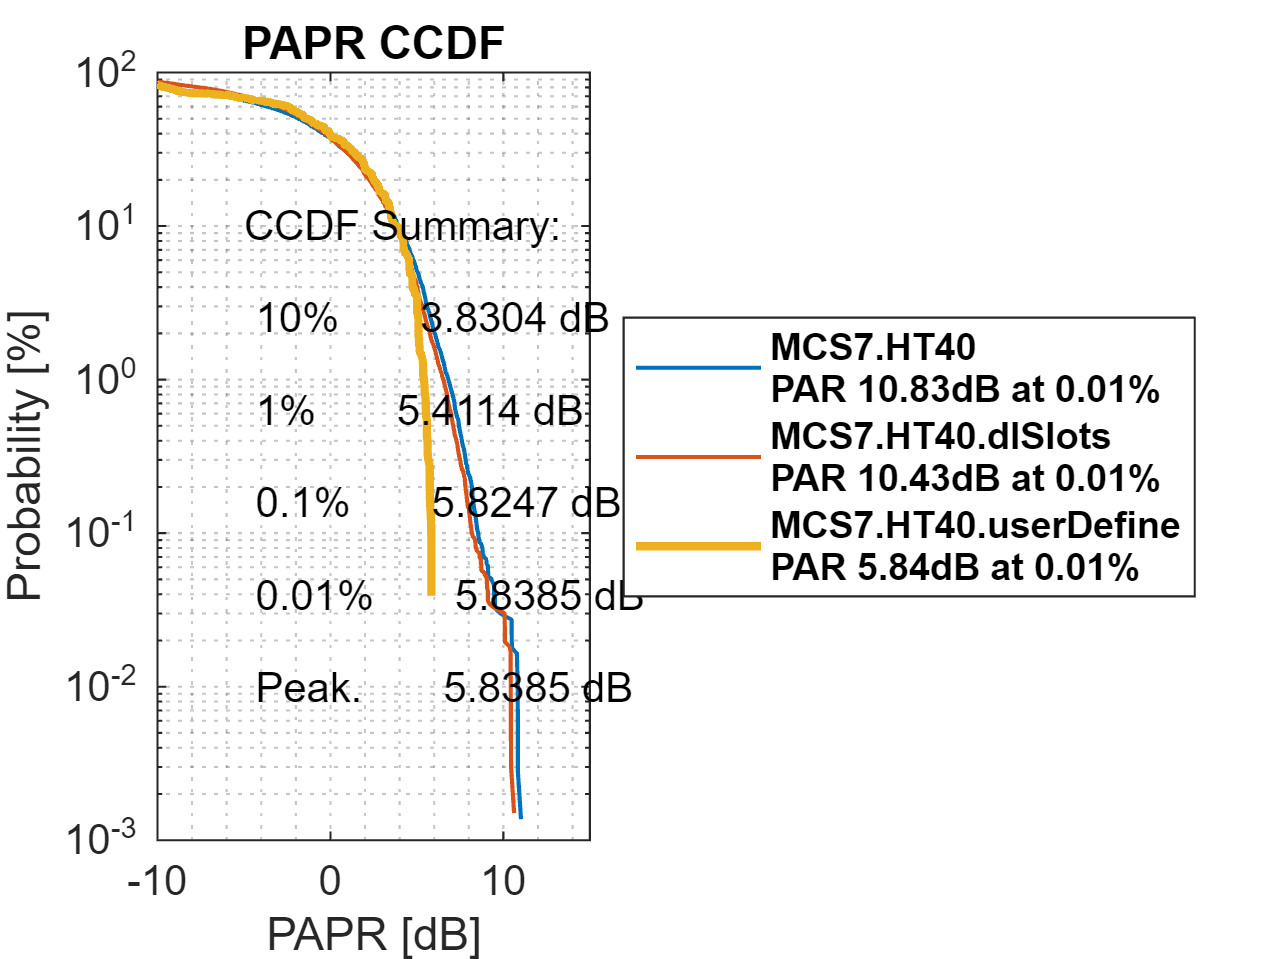

ccdfVal_wv_userDefine =        5.8385



if 0 % 2024-04-16, get wv packet timing line
    timingInfo = pltWlan.timing(pltWlan, wv, fsMHz, [], {091202,dispLegd_format})
    durationData = timingInfo.tDATA;
    durationData_start_us = (timingInfo.tPREAMBLE_NonHT+timingInfo.tPREAMBLE)
    durationData_end_us = timingInfo.txTIME
    dlSlots_tmp = [durationData_start_us*1e-6*fs:durationData_end_us*1e-6*fs]';1
    pltComm.TIME(wv, {123}, [], 'usec')
end

if 1 % plot wv ccdf
    ccdfVal_wv = PLOT_COMM.ccdf([], wv, 0.01, {[091203], [dispLegd_format], 'CCDF'})
    ccdfVal_wv_dlSlots = PLOT_COMM.ccdf([], wv(dlSlots), 0.01, {[091203], [dispLegd_format+".dlSlots"], 'CCDF'})
    ccdfVal_wv_userDefine = PLOT_COMM.ccdf([], wv(1:16e-6*fs), 0.01, {[091203], dispLegd_format+".userDefine", 'CCDF'})
end


if 0 % evaluate wv
    close all
    demod_wv = wlanDemodulation(wv,passParams,'tx')
    demod_wv.evmRMS
end
% end


#### Transmitter -  Apply Noise - Before PA

isNoiseFloor = 0;
if 1 * isNoiseFloor % shift
    n0_dBmHz_set = -150
    [wvNoise, noise0] = rfSim_noise(wv, 'NoisePowerDbmHz', n0_dBmHz_set, fs);
    noise0_dBmHz = powerDbm(noise0,'rms',[],fs,dlSlots)

    % export
    wv = wvNoise;
    if 0 % evaluate wv
        passParams.finalSignal = wvNoise;
        demod_txNoise = wlanDemodulation(wvNoise, passParams, 'tx')
        demod_txNoise.evmRMS
    end
end

#### Transmitter - Characterize PA and Signal

dispLegd_LUT = '0527SIMCW'

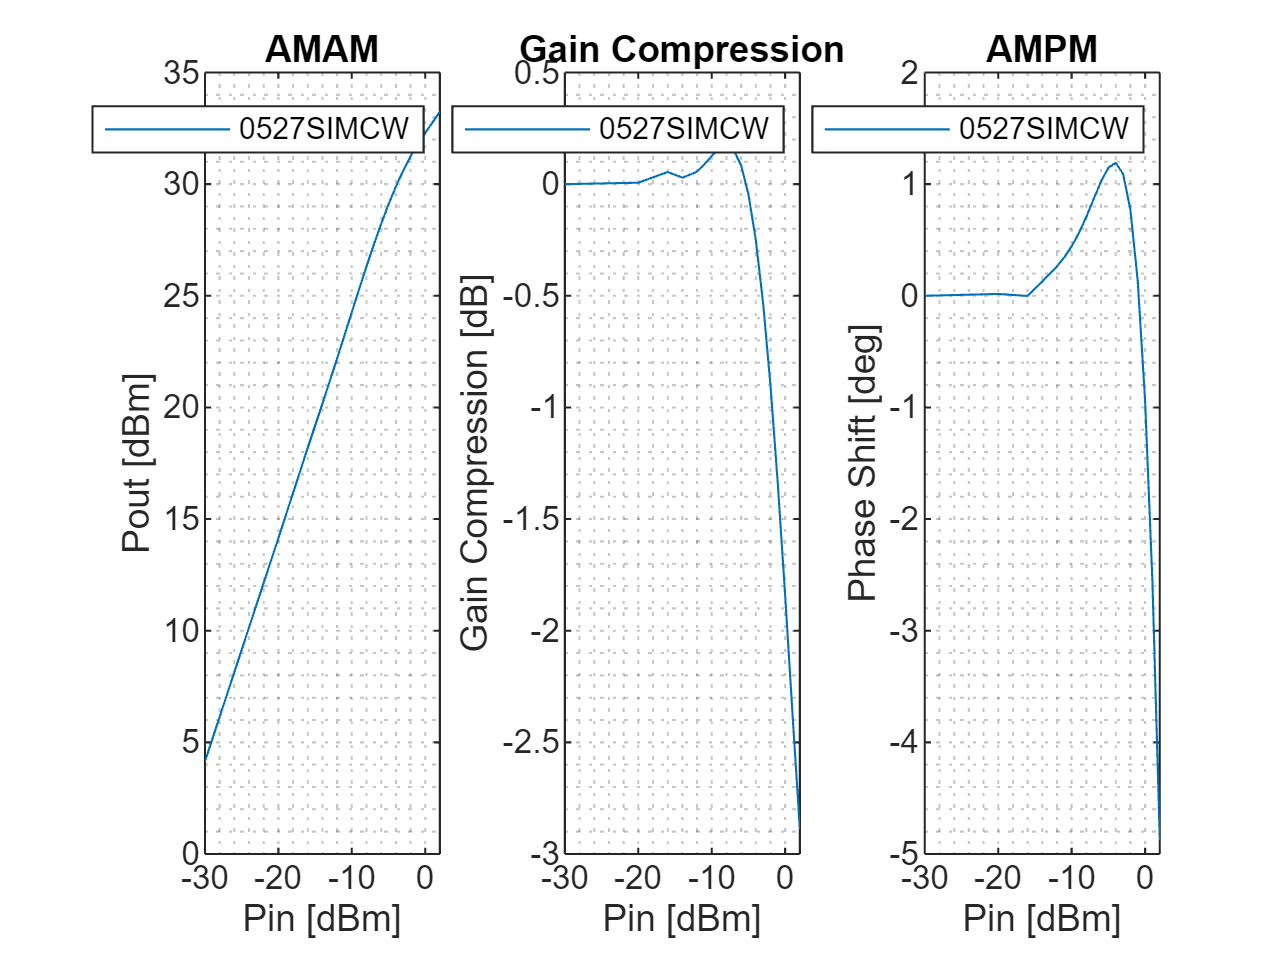

paModel_tolerance_dB = 0; % set pa toleranace
paLinearGain_dB = 34.8; % set pa toleranace

if ~isMultiStage
    clear paModel
    paModel.Method = "Cubic polynomial";
    paModel.AMPMConversion = 0.0;
    paModel.LinearGain = paLinearGain_dB;

    switch PaModel_type
        case 'OP1dB'
            paModel.TOISpecification = "OP1dB";
            paModel.OP1dB = 30.0 - paModel_tolerance_dB;
        case 'OPsat'
            paModel.TOISpecification = "OPsat";
            paModel.OPsat = 34 + 1
        case 'OIP3'
            paModel.TOISpecification = "OIP3";
            paModel.OIP3 = 34 + 4;
        case 'LUT'
            paModel.Method = 'Lookup table'; % set pa model method to 'Lookup table'
            dispLegd_LUT = paModel_LUT_sheet

            % set pa model LUT from paData.xlsx
            [paModel.LookupTable, LookupTable] = paLookupTable_process('paData.xlsx',dispLegd_LUT,[-30,2],091204,1);
            paLinearGain_dB = paModel.LookupTable(1,2) - paModel.LookupTable(1,1);

        case 'LUT_userDefine' % set LUT by user define
            clear setLUT
            setLUT.PinLinearDbm = [-40:5:-15];
            setLUT.GainLinearDb = 34.5;
            if 1 % set lutCase
                lutCase = {'exponentExpension', 'exponent', 'lutCase1'};
                lutCase = {'exponentExpension', 'linear', 'lutCase2'};
                % lutCase = {'linearExpension', 'exponent', 'lutCase3'};
                % lutCase = {'linearExpension', 'linear', 'lutCase4'};
                % lutCase = {'compression', 'exponent', 'lutCase5'};
                % lutCase = {'compression', 'linear', 'lutCase6'};
            end
            lutGainType = lutCase{1};
            lutPhasType = lutCase{2};
            dispLegd_LUT = ['Gain: ',lutGainType, ', Phase: ',lutPhasType]

            if 1 % reference of pout dbm
                setLUT.PoutDbm = [setLUT.PinLinearDbm + setLUT.GainLinearDb, 22.5  27.6 30.3 31.0 31.7 32.5 33.1]';
            end
            switch lutGainType
                case 'exponentExpension'
                    setLUT.GainCompressionDb = [zeros(size(setLUT.PinLinearDbm)), 0.1 0.2 -0.15 -0.4 -0.7 -0.9 -1.2]';
                case 'linearExpension'
                    setLUT.GainCompressionDb = [0 0.01 0.02 0.04 0.06 0.1, 0.05 0. -0.15 -0.4 -0.7 -0.9 -1.2]';
                case 'compression'
                    setLUT.GainCompressionDb = [zeros(size(setLUT.PinLinearDbm)), -0.05 -0.18 -0.3 -0.4 -0.5 -0.8 -1]';
            end
            switch lutPhasType
                case 'exponent'
                    setLUT.PhaseShiftDeg = [zeros(size(setLUT.PinLinearDbm)), 0.04 0.22 0.5 0.6 1 0.4 -0.5]';
                case 'linear'
                    setLUT.PhaseShiftDeg = [0 0 0.01 0.02 0.04 0.08, 0.16 0.32 0.2 0.15 0.1 0 -0.5]';
                    setLUT.PhaseShiftDeg = [0 0 0.01 0.02 0.04 0.08, 0.12 0.24 0.36 0.15 0.1 0 -0.5]';
            end
            if  numel(setLUT.PoutDbm)~=numel(setLUT.GainCompressionDb)|| numel(setLUT.GainCompressionDb)~=numel(setLUT.PhaseShiftDeg)
                error('check the setLUT, length should be equal')
            end
    end

else % multi-stages pa
    clear paModel paMd1 paMd2 paMd3 paMd4
    switch isPaModel
        case 'OP1dB'
            paMd1.Method = "Cubic polynomial"; % pa model 1
            paMd1.LinearGain = 12;
            paMd1.TOISpecification = "OP1dB";
            paMd1.OP1dB = 14;
            paMd2.Method = "Cubic polynomial";
            paMd2.LinearGain = 11;
            paMd2.TOISpecification = "OP1dB";
            paMd2.OP1dB = 30;
            paMd3.Method = "Cubic polynomial";
            paMd3.LinearGain = 10;
            paMd3.TOISpecification = "OP1dB";
            paMd3.OP1dB = 38;
            paMd3.AMPMConversion = 0;
            paMd3.PowerLowerLimit = 10.8000;
            paMd3.PowerUpperLimit = 20.8000;
            paModel = {paMd1, paMd2, paMd3};
        case 'OIP3'
            paMd1.Method = "Cubic polynomial"; % pa model 1
            paMd1.LinearGain = 12;
            paMd1.TOISpecification = "OIP3";
            paMd1.OIP3 = 14+10;
            paMd2.Method = "Cubic polynomial";
            paMd2.LinearGain = 11;
            paMd2.TOISpecification = "OIP3";
            paMd2.OIP3 = 30+11;
            paMd3.Method = "Cubic polynomial";
            paMd3.LinearGain = 10;
            paMd3.TOISpecification = "OIP3";
            paMd3.OIP3 = 38+11;
            paMd3.AMPMConversion = 0;
            paMd3.PowerLowerLimit = 10.8000;
            paMd3.PowerUpperLimit = 20.8000;
            paModel = {paMd1, paMd2, paMd3};
        case 'LUT'
            [lut_mx1, LookupTable1] = paLookupTable_process('paData.xlsx','0614SIMCW1M',[-50,50],[],1);
            [lut_mx2, LookupTable2] = paLookupTable_process('paData.xlsx','0614SIMCW2M',[-50,50],[],1);
            [lut_mx3, LookupTable3] = paLookupTable_process('paData.xlsx','0614SIMCW3M',[-50,50],[],1);
            paMd1.Method = "Lookup table"; % pa model 1
            paMd2.Method = "Lookup table";
            paMd3.Method = "Lookup table";
            if ~strcmpi(paModel_methology,'RFSIMPA')
                paMd1.LookupTable = lut_mx1;
                paMd2.LookupTable = lut_mx2;
                paMd3.LookupTable = lut_mx3;
            else
                paMd1.LookupTable = LookupTable1;
                paMd2.LookupTable = LookupTable2;
                paMd3.LookupTable = LookupTable3;
            end
            paModel = {paMd1, paMd2, paMd3}
            if 0
                figure(0530), subplot(1,3,1), plot(LookupTable.PinDbm, LookupTable.PoutDbm,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMAM'), hold on, grid minor, legend
                figure(0530), subplot(1,3,2), plot(LookupTable.PoutDbm, LookupTable.GainDb-0*LookupTable.GainDb(1),'DisplayName',dispLegd_LUT, 'LineWidth',2), title('GainCompression'), hold on, grid minor, legend
                figure(0530), subplot(1,3,3), plot(LookupTable.PoutDbm, LookupTable.PhaseShiftDeg,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMPM'), hold on, grid minor, legend
            end
            if 0
                paMd4.Method = "Lookup table";
                paMd4.LookupTable = rfSim_pa_amam_model(LookupTable3.PoutDbm, LookupTable3.GainDb, LookupTable3.GainDb(1), 0.5, 0619)
                paModel{end} = paMd4
            end
        case {'OP1dB+LUT','mixing case'}
            paMd1.Method = "Cubic polynomial"; % pa model 1
            paMd1.LinearGain = 12;
            paMd1.TOISpecification = "OP1dB";
            paMd1.OP1dB = 14;
            paMd2.Method = "Cubic polynomial";
            paMd2.LinearGain = 11;
            paMd2.TOISpecification = "OP1dB";
            paMd2.OP1dB = 30;
            paMd4.Method = "Lookup table";
            [lut_mx4, LookupTable4] = paLookupTable_process('paData.xlsx','0614SIMCW3M',[-50,50],[],1);
            if ~strcmpi(paModel_methology,'RFSIMPA')
                paMd4.LookupTable = lut_mx4;
            else
                paMd4.LookupTable = LookupTable4;
            end
            paModel = {paMd1, paMd2, paMd4};
    end
end

#### Transmitter - Apply CFR - Release V2.0 - 2024-09-25

isCFR = 0

isCFR =      0


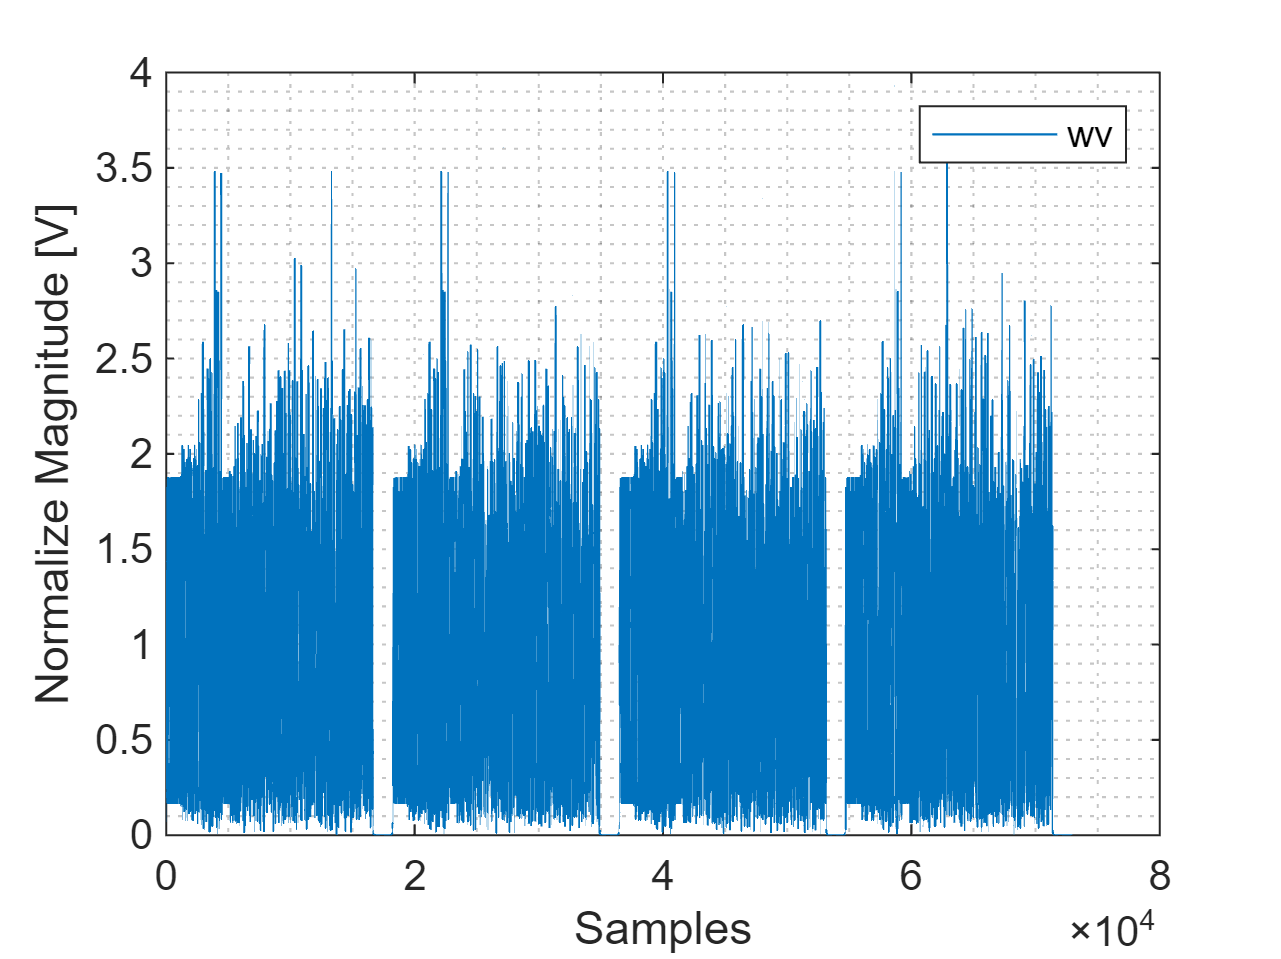


ans =

     []



PLOT_COMM.time([], wv, [], 'samples', {0925, 'wv'})

ccdfVal_wv = PLOT_COMM.ccdf([], wv, 0.01) % check ccdf

ccdfVal_wv =        10.829



if isCFR
    % set cfr
    cfr_paprDb = 8
    cfr_nIteration = 20
    wv_cfr = dfe_cfr_nco_2(wv, cfr_paprDb, [], [], cfr_nIteration, []);
    powerDbm(wv_cfr)
    demod_wvCfr = wlanDemodulation(wv_cfr,passParams,'tx')
    wlanDemodulation(wv,{passParams,'wv'},'tx')
    wv = wv_cfr;
end

#### Transmitter - Apply PA and Tuning to Target Output Power


paOutputPower_tolerance_dB = 0.2; % set output power tolerance
% paInPowerBoost_dB = 0;
deltaTarget_dB = paOutputPower_tolerance_dB;
ii = 1;
paInputPowerDbm_set = paOutputPower_target_dBm - paLinearGain_dB; % get initial pa input power
SIMULATING_tuningPower = 1;
paOutputPower_dBm_vec = -1e10;
if 0
    dlSlots = true(size(wv));
end

while SIMULATING_tuningPower
    clear paInSignal paSignal

    if 1 % set pa input power
        paInSignal = wv./rms(wv(dlSlots)).*10^(paInputPowerDbm_set/20)*sqrt(1/1000);
        paInSignal_dBm = 10*log10(mean(abs(paInSignal(dlSlots)).^2)) + 30
    else
        paInSignal = powerDbm(wv,'set',paInputPowerDbm_set,'dBm',dlSlots);
        paInSignal_dBm = powerDbm(paInSignal,'rms',[],[],dlSlots)
    end
    % %
    % % if 0 * isNoiseFloor % Apply noise floor
    % %     n0_dBmHz_set = -150
    % %     [paInSignal, noise0] = rfSim_noise(paInSignal, 'NoisePowerDbmHz', n0_dBmHz_set, fs);
    % %     noise0_dBmHz = powerDbm(noise0,'rms',[],fs,dlSlots)
    % % end

    if 0 % check
        demod_paIn = wlanDemodulation(paInSignal,passParams,'tx')
    end

    if isfield(paModel,'AMPMConversion') % set pa input boundary for paModel.AMPMConversion
        paModel.PowerLowerLimit = paInSignal_dBm - 5; % 5 is margin
        paModel.PowerUpperLimit = paInSignal_dBm + 11; % 11 is PAPR
    end

    % apply pa model
    switch paModel_methology
        case 'commMemorylessNonlinearity'
            [paSignal, paSignal_info_stages, paSignal_stages] = rfSim_pa_stages(paInSignal,'COMM',paModel,dlSlots);
        case 'RFSIMPA'
            [paSignal, paSignal_info_stages, paSignal_stages] = rfSim_pa_stages(paInSignal,'RFSIM',paModel,dlSlots);
    end


    if 0 % evaluate - pa output
        demod_paSignal = wlanDemodulation(paSignal, passParams, 'tx')
        paSignal_dBm = powerDbm(paSignal, 'rms', [], 'dBm', dlSlots)
        PLOT_COMM.time([], paInSignal, fs/1e6, 'us', {061203, ['pa input']})
        PLOT_COMM.time([], paSignal_stages(:,1), fs/1e6, 'us', {061203, ['pa stage 1']})
        PLOT_COMM.time([], paSignal_stages(:,2), fs/1e6, 'us', {061203, ['pa stage 2']})
        PLOT_COMM.time([], paSignal_stages(:,3), fs/1e6, 'us', {061203, ['pa stage 3']})
        pltComm.AMAM([paInSignal(dlSlots), paSignal_stages(dlSlots,1)], {061901, ['pa stage 1']})
        pltComm.AMAM([paInSignal(dlSlots), paSignal_stages(dlSlots,2)], {061901, ['pa stage 2']})
        pltComm.AMAM([paInSignal(dlSlots), paSignal_stages(dlSlots,3)], {061901, ['pa stage 3']})

        switch isPaModel
            case 'LUT'
                if 0
                    figure(061901), subplot(1,3,1), plot(LookupTable.PinDbm, LookupTable.PoutDbm,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMAM'), hold on, grid minor, legend
                    figure(061901), subplot(1,3,2), plot(LookupTable.PinDbm, LookupTable.GainDb-0*LookupTable.GainDb(1),'DisplayName',dispLegd_LUT, 'LineWidth',2), title('GainCompression'), hold on, grid minor, legend
                    figure(061901), subplot(1,3,3), plot(LookupTable.PoutDbm, LookupTable.PhaseShiftDeg,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMPM'), hold on, grid minor, legend
                end
        end
    end

    % if 0
    %     results_pa1 = wlanDemodulation(paSignal_stages(:,1), passParams, 'tx')
    %     results_paIn = wlanDemodulation(paInSignal(:,1), passParams, 'tx')
    % end

    % % if 0 % evalute - cw signal
    % %     for k=-20:2:5
    % %         cw = 1*sqrt(0.001) * 10.^([k]/20) .* [ones(size(paInSignal))];
    % %         powerDbm(cw,'rms')
    % %         cond.winType = 'rect'
    % %         pltComm.sa(pltComm, cw, {061301, 'cw'}, [], 20, cond,'dBm')
    % %         powerDbm(cw,'rms')
    % %         [cwPaSignal, paSignal_info_stages, paSignal_stages] = rfSim_pa_stages(cw,'COMM',paModel,[],[]);
    % %
    % %         if 0
    % %             pltParms.isNormGC = 11.65;
    % %             PLOT_COMM.amam([], [cw,paSignal_stages(:,1)], {061206, [], [], 'r'})
    % %             pltParms.isNormGC = 12.5 + pltParms.isNormGC;
    % %             PLOT_COMM.amam([], [cw,paSignal_stages(:,2)], {061206, [], [], 'g'})
    % %             pltParms.isNormGC = 10.24 + pltParms.isNormGC;
    % %             PLOT_COMM.amam([], [cw,paSignal_stages(:,3)], {061206, [], [], 'b'})
    % %         elseif 1
    % %             pltParms.isNormGC = 11.65;
    % %             PLOT_COMM.amam([], [cw,paSignal_stages(:,1)], {061206, [], [], 'r'})
    % %             pltParms.isNormGC = 12.5;
    % %             PLOT_COMM.amam([], [paSignal_stages(:,1),paSignal_stages(:,2)], {061206, [], [], 'g'})
    % %             pltParms.isNormGC = 10.24;
    % %             PLOT_COMM.amam([], [paSignal_stages(:,2),paSignal_stages(:,3)], {061206, [], [], 'b'})
    % %             pltParms.isNormGC = 11.65+12.5+10.24;
    % %             PLOT_COMM.amam([], [cw,paSignal_stages(:,3)], {061206, [], [], 'm'})
    % %         end
    % %
    % %         if 0
    % %             mk = [30e6:10e6:60e6];
    % %             sinWave = cwGen(fs, numel(paInSignal), (-15-10*log10(numel(mk)))*ones(size(mk)), mk, 0, 061204, 0);
    % %             [swPaSignal, sw_paPwr_stages, sw_paSig_stages] = rfSim_pa_stages(sinWave,'COMM',paModel,[],[]);
    % %
    % %             plot_comm([sinWave(:,1)],fs,'spectra',pltParms, {061301, ['pa input']},mk);
    % %             plot_comm([sw_paSig_stages(:,1)],fs,'spectra',pltParms, {061301, ['pa stage 1']},mk);
    % %             plot_comm([sw_paSig_stages(:,2)],fs,'spectra',pltParms, {061301, ['pa stage 2']},mk);
    % %             plot_comm([sw_paSig_stages(:,3)],fs,'spectra',pltParms, {061301, ['pa stage 3']},mk);
    % %             xlim([0 150]), title("Two Tone Signal")
    % %             struct2table(sw_paPwr_stages)
    % %         end
    % %     end
    % % end

#### Transmitter - Apply Flatness - After PA

    % % if isPaFlatness
    % %     flatnessMax_dB = 2 % set max flatness
    % %     bw = passParams.currentBw;
    % %     flatFreqHz = bw/2 * [0:1:configParamsWG.osr];
    % %     flatMagnDb = -flatnessMax_dB * [0:1:configParamsWG.osr] + flatnessMax_dB/2;
    % %     [paSignalFlat, b_flat] = rfSim_fltaness(paSignal, fs, flatMagnDb, flatFreqHz, 10e3);
    % %
    % %     % export
    % %     paSignal = paSignalFlat;
    % %     paSignal_dBm = powerDbm(paSignalFlat,'rms',[],[],dlSlots)
    % %
    % %     if 0 % check
    % %         pltComm.sa(pltComm, b_flat/max(b_flat), {061301, 'b_flat'}, [], 20, cond,'dBm')
    % %         pltComm.aclr(pltComm, )
    % %
    % %         pltComm.sa(pltComm, b_flat/max(b_flat), {0527, 'flatness filter'}, [], 0.1)
    % %         plotSpectrum(b_flat,fs,{123},{0,[],100})
    % %         pltParms_b = pltParms;
    % %         pltParms_b.rbw = 1
    % %         plot_comm(b_flat, fs, 'spectra', pltParms_b, {0527, ['flatness']}); hold on
    % %         plot_wlan(paSignalFlat, fs, 'aclr', passParams.cfgFormat, passParams.packetParams.NumPackets, {0415,'lna signal flatness','ACLR'})
    % %     end
    % % else
    % %     flatnessMax_dB = 0;
    % % end

    % check pa output power

paInSignal_dBm =         -9.34


paSignal_dBm =        24.786


deltaTarget_dB =        -0.014


paInSignal_dBm =        -9.326


paSignal_dBm =        24.799


deltaTarget_dB =        -0.001


paInSignal_dBm =        -9.325


paSignal_dBm =          24.8


deltaTarget_dB =      0


    % paSignal_dBm = powerDbm_v1(paSignal,dlSlots)
    paSignal_dBm = powerDbm(paSignal,'rms',[],[],dlSlots)

paSignal_dBm =          24.8


    paOutputPower_dBm_vec = [paOutputPower_dBm_vec, paSignal_dBm];

deltaTarget_dB =      0


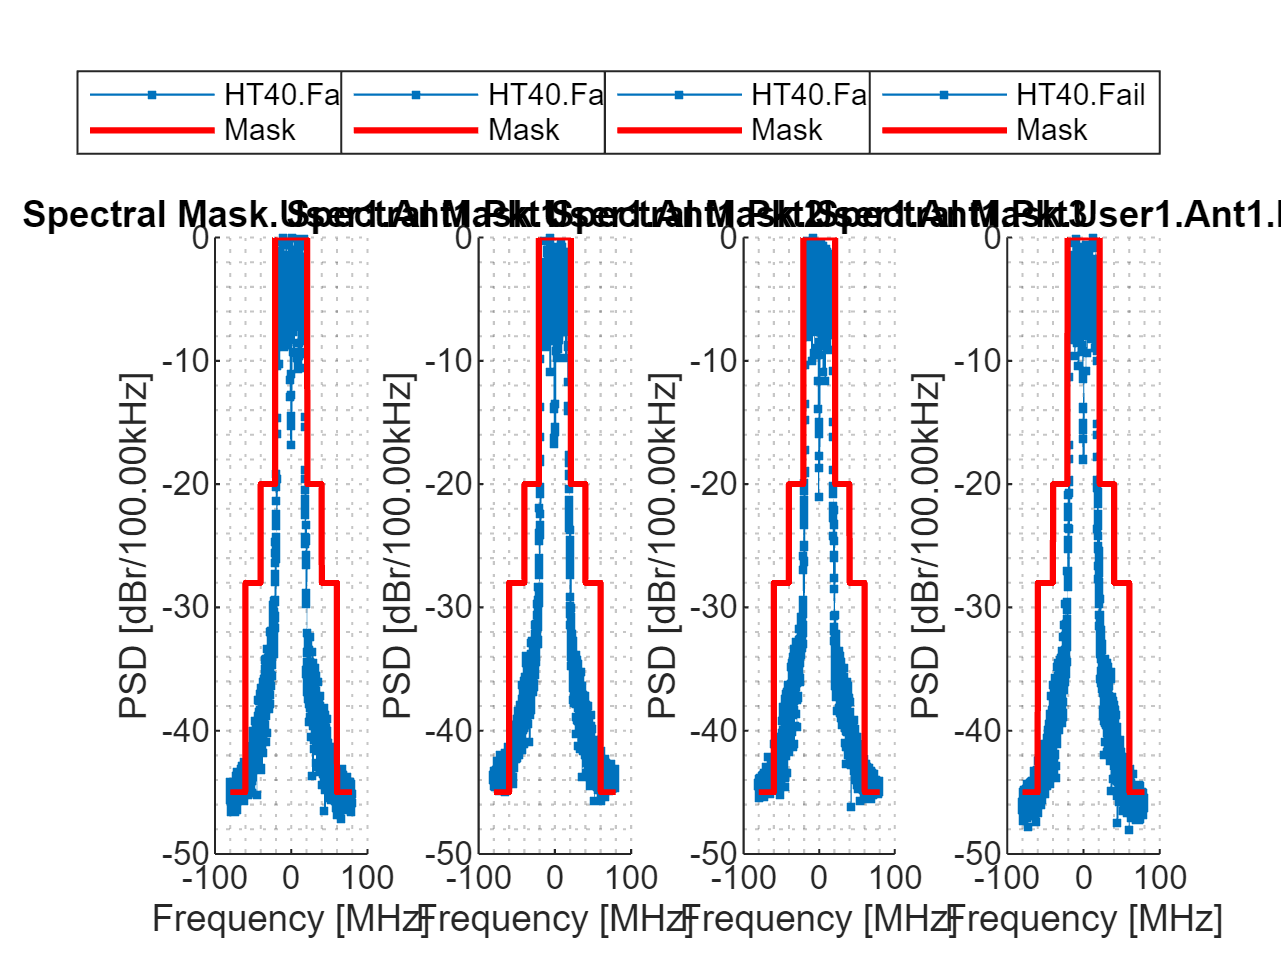

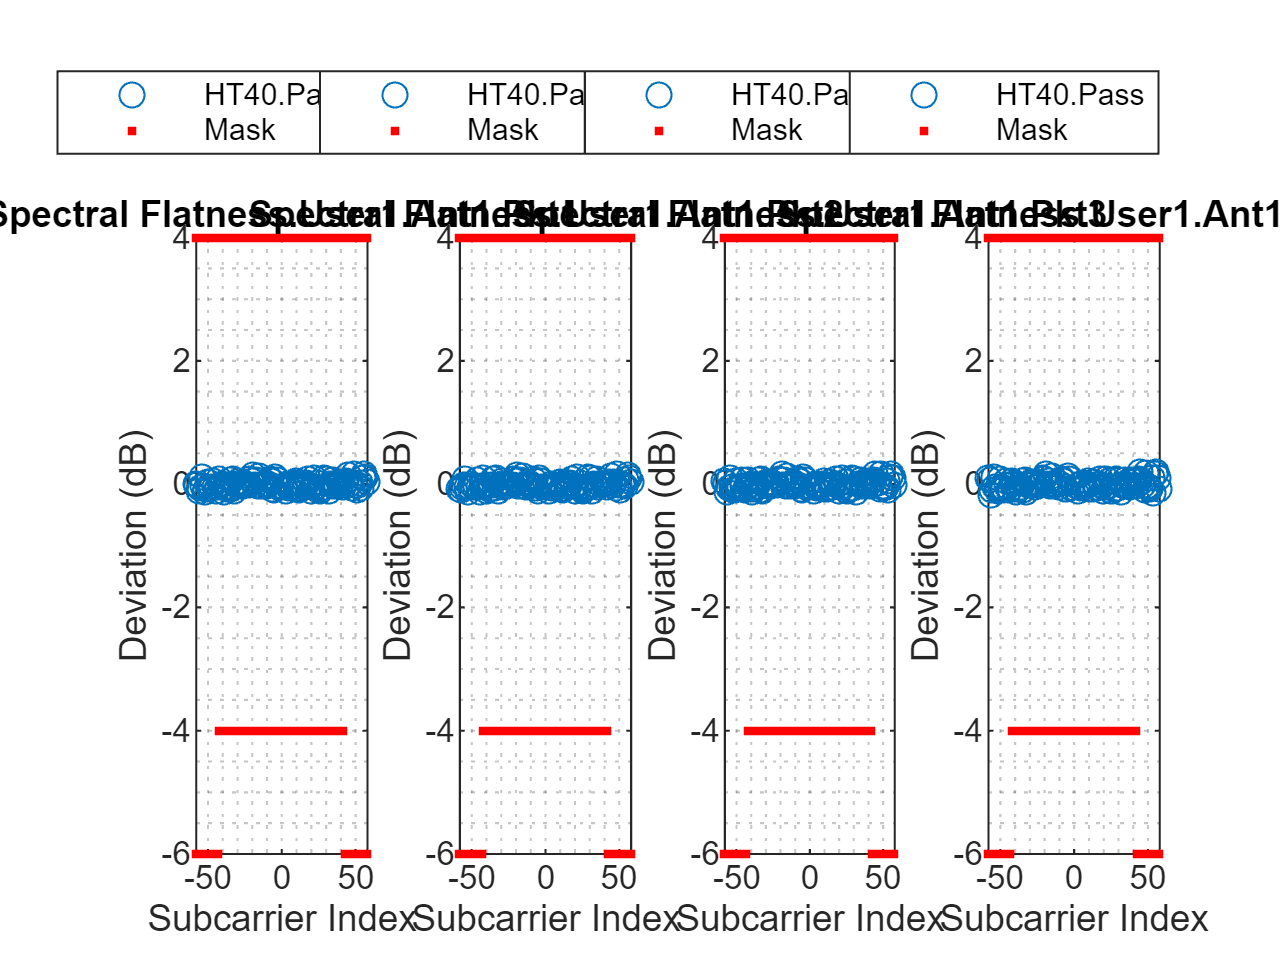

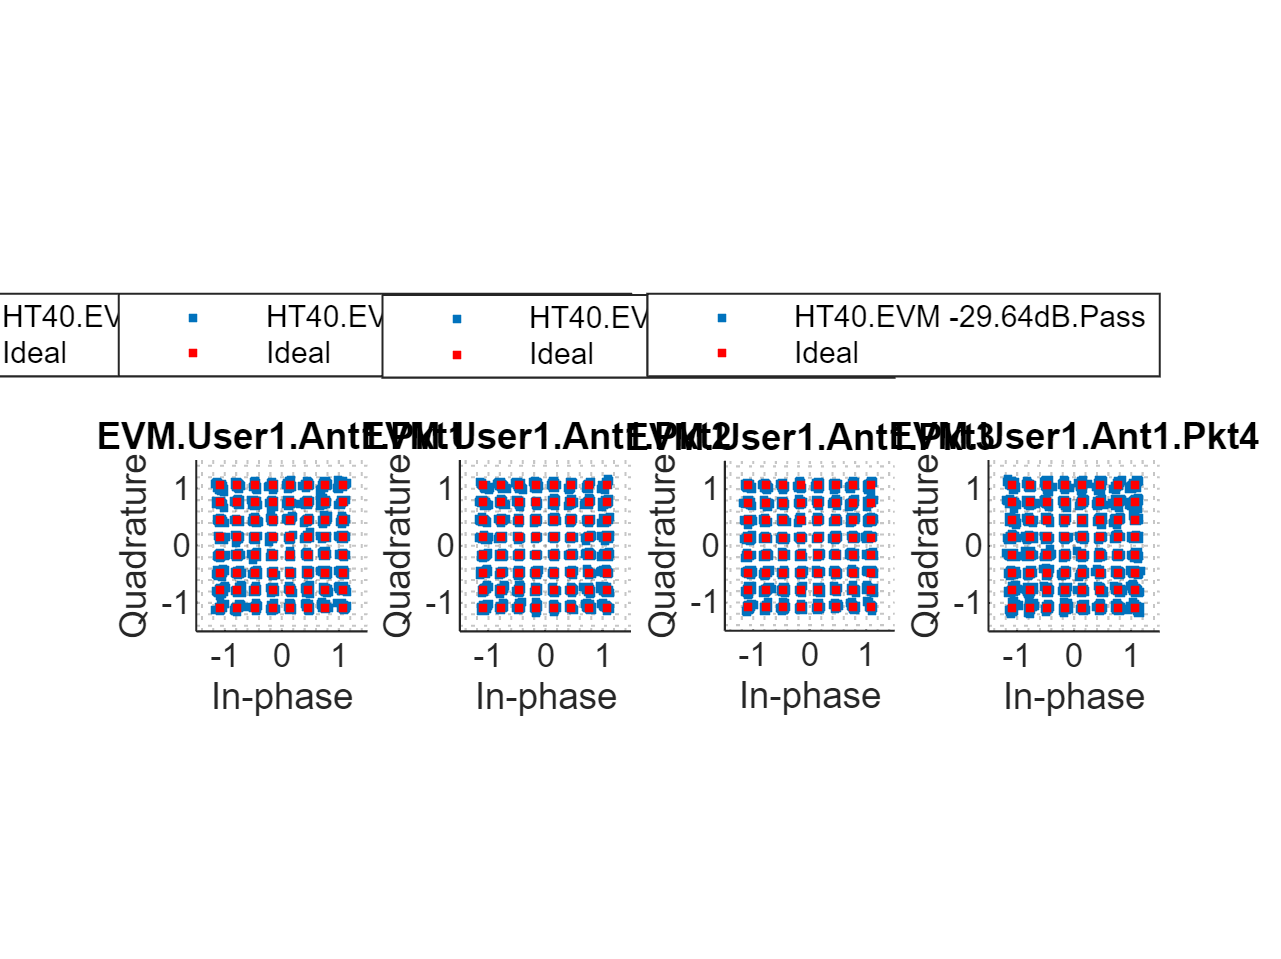

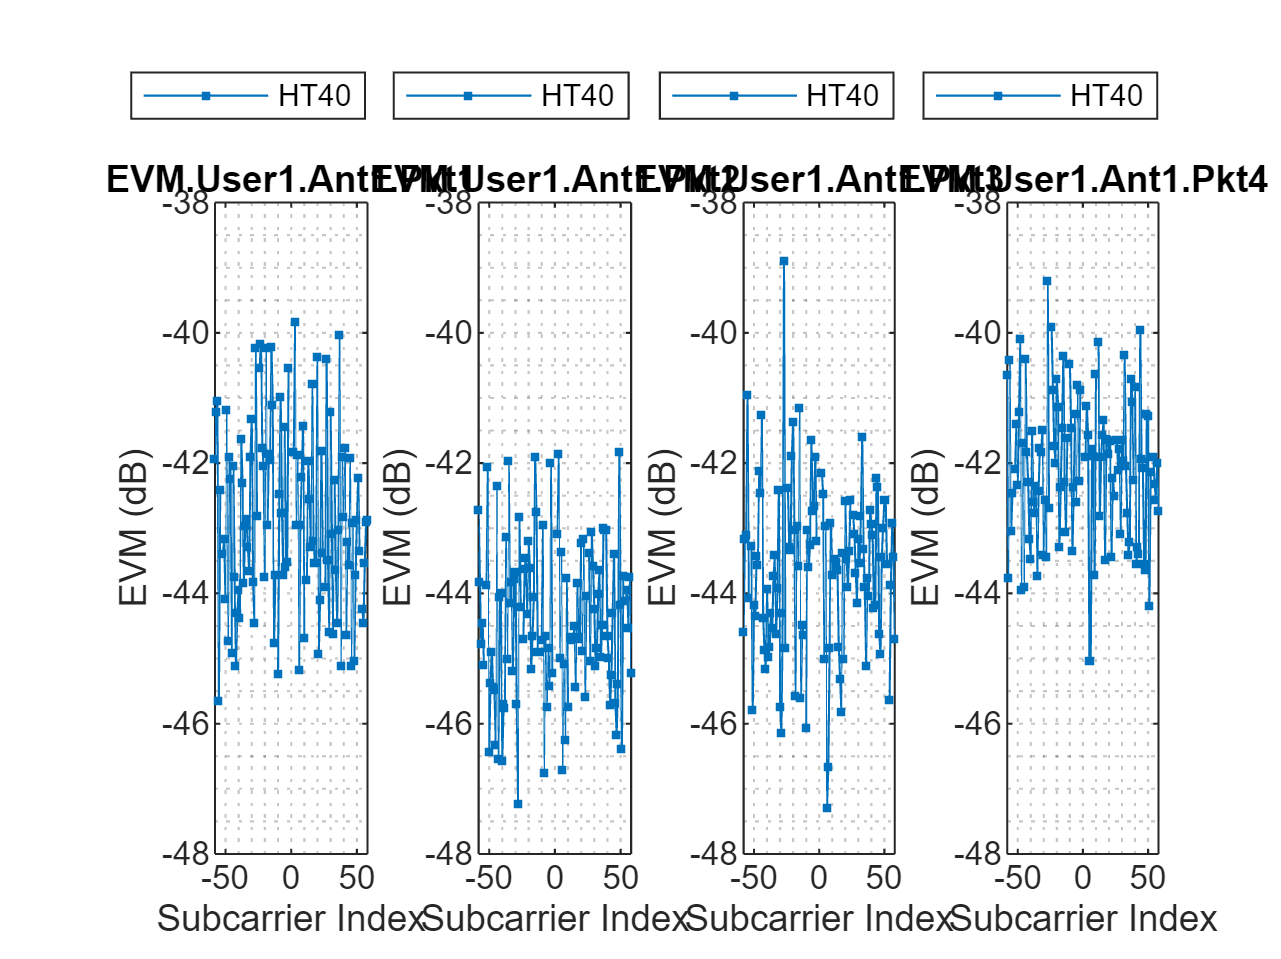

demod_finalSignal = struct with fields:
                isEVMPass: [1 1 1 1]
               isFlatPass: [1 1 1 1]
               isMaskPass: [0 0 0 0]
                   evmRMS: [-30.318 -31.947 -31.134 -29.635]
                 evmPerSc: {[108×1 double]  [108×1 double]  [108×1 double]  [108×1 double]}
            flatDeviation: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
                  evmSpec: [1×4 table]
                 flatSpec: [1×11 table]
                 maskSpec: [1×7 table]
    outputPowerPerPktsDbm: [24.84 24.885 24.82 24.73]


    ii=ii+1;

    % 2024-03-21, To get the fixed output power
    deltaTarget_dB = round(paSignal_dBm - paOutputPower_target_dBm, 3)
    if deltaTarget_dB > paOutputPower_tolerance_dB

        paInputPowerDbm_set = paInputPowerDbm_set - paOutputPower_tolerance_dB/2; % decrease the boostDb
        paSignal_tmp = paSignal;
        continue
    elseif any(diff(paOutputPower_dBm_vec)<0) || ii>20 % saturation
        SIMULATING_tuningPower = 0;
        paSignal = paSignal_tmp;
        paSignal_dBm = paOutputPower_dBm_vec(end-1);
    elseif deltaTarget_dB < 0
        paInputPowerDbm_set = paInputPowerDbm_set - deltaTarget_dB; % increase the boostDb
        paSignal_tmp = paSignal;
        continue
    else
        SIMULATING_tuningPower = 0;
    end

    % export
    passParams.finalSignal = paSignal;

    % % if isMultiStage * ~SIMULATING_tuningPower % evalute - pa output stages
    % %     results_pa_stage1 = wlanDemodulation(paSignal_stages(:,1), passParams, 'tx')
    % %     results_pa_stage2 = wlanDemodulation(paSignal_stages(:,2), passParams, 'tx')
    % %     results_pa_stage3 = wlanDemodulation(paSignal_stages(:,3), passParams, 'tx')
    % % end
end

#### Transmitter - Apply wlanDemodulation and Measurements

paSignal_dBm = powerDbm(passParams.finalSignal, 'rms', [], 'dBm', dlSlots)
deltaTarget_dB = round(paSignal_dBm - paOutputPower_target_dBm, 3)

if deltaTarget_dB < 0 || deltaTarget_dB > paOutputPower_tolerance_dB + 0.1 % check deltaTarget_dB
    error('pa output power could not met the target power')
end
demod_finalSignal = wlanDemodulation(passParams.finalSignal, passParams, 'tx')

% if 0
%     demod_finalSignal.evmRMS
%     20*log10(evm(paSignal,paInSignal)/100)
%     powerDbm_v1(paSignal,dlSlots)
%     struct2table(paPowerDbm_stages)
%     plot_comm(wv(:), fs, 'time', [], {03121, [dispLegd_format]}); hold on
%     plot([0:numel(wv)-1]'./fs*1e6, dlSlots)
% end

% % if 0 % multi-stage
% %     pltParms.isNormGC = 1;
% %     plot_comm([paInSignal,paSignal_stages(:,1)],[],'amam',pltParms, {0614, ['pa stage 1'], []});
% %     plot_comm([paInSignal,paSignal_stages(:,2)],[],'amam',pltParms, {0614, ['pa stage 2'], []});
% %     plot_comm([paInSignal,paSignal_stages(:,3)],[],'amam',pltParms, {0614, ['pa stage 3'], []});
% % end

% %             if 0
% %                 mk = fs/8 + [0 1]*fs/16
% %                 sinWave = cwGen(fs, numel(paInSignal), (paInSignal_dBm-10*log10(numel(mk)))*ones(size(mk)), mk, 0, 061204, 0);
% %                 [swPaSignal, sw_paPwr_stages, sw_paSig_stages] = rfSim_pa_stages(sinWave,'COMM',paModel,[],[]);
% %
% %                 pltParms_sw = pltParms;
% %                 pltParms_sw.rbw = 1;
% %                 plot_comm([sinWave(:,1)],fs,'spectra',pltParms_sw, {061301, ['pa input']},mk);
% %                 val = plot_comm([sw_paSig_stages(:,1)],fs,'spectra',pltParms_sw, {061301, ['pa stage 1']},[2*mk(1)-mk(2), mk, 2*mk(2)-mk(1)]);
% %                 nStage = 1;
% %                 sw_im3_stage.Stage(nStage,:) = nStage;
% %                 sw_im3_stage.PIM3LDbm(nStage,:) = val.plot.MarkerPowerDbm(1);
% %                 sw_im3_stage.PoLDbm(nStage,:) = val.plot.MarkerPowerDbm(2);
% %                 sw_im3_stage.PoHDbm(nStage,:) = val.plot.MarkerPowerDbm(3);
% %                 sw_im3_stage.PIM3HDbm(nStage,:) = val.plot.MarkerPowerDbm(4);
% %                 sw_im3_stage.OIP3LDbn(nStage,:) = val.plot.MarkerPowerDbm(2) + 0.5*(val.plot.MarkerPowerDbm(2)-val.plot.MarkerPowerDbm(1))
% %
% %                 val = plot_comm([sw_paSig_stages(:,2)],fs,'spectra',pltParms_sw, {061301, ['pa stage 2']},[2*mk(1)-mk(2), mk, 2*mk(2)-mk(1)]);
% %                 nStage = 2;
% %                 sw_im3_stage.Stage(nStage,:) = nStage;
% %                 sw_im3_stage.PIM3LDbm(nStage,:) = val.plot.MarkerPowerDbm(1);
% %                 sw_im3_stage.PoLDbm(nStage,:) = val.plot.MarkerPowerDbm(2);
% %                 sw_im3_stage.PoHDbm(nStage,:) = val.plot.MarkerPowerDbm(3);
% %                 sw_im3_stage.PIM3HDbm(nStage,:) = val.plot.MarkerPowerDbm(4);
% %                 sw_im3_stage.OIP3LDbn(nStage,:) = val.plot.MarkerPowerDbm(2) + 0.5*(val.plot.MarkerPowerDbm(2)-val.plot.MarkerPowerDbm(1))
% %
% %                 val = plot_comm([sw_paSig_stages(:,3)],fs,'spectra',pltParms_sw, {061301, ['pa stage 3']},[2*mk(1)-mk(2), mk, 2*mk(2)-mk(1)]);
% %                 nStage = 3;
% %                 sw_im3_stage.Stage(nStage,:) = nStage;
% %                 sw_im3_stage.PIM3LDbm(nStage,:) = val.plot.MarkerPowerDbm(1);
% %                 sw_im3_stage.PoLDbm(nStage,:) = val.plot.MarkerPowerDbm(2);
% %                 sw_im3_stage.PoHDbm(nStage,:) = val.plot.MarkerPowerDbm(3);
% %                 sw_im3_stage.PIM3HDbm(nStage,:) = val.plot.MarkerPowerDbm(4);
% %                 sw_im3_stage.OIP3LDbn(nStage,:) = val.plot.MarkerPowerDbm(2) + 0.5*(val.plot.MarkerPowerDbm(2)-val.plot.MarkerPowerDbm(1))
% %
% %                 xlim([0 fs/2/1e6]), title("Two Tone Signal"), legend('Location','eastoutside')
% %                 struct2table(sw_paPwr_stages)
% %                 struct2table(sw_im3_stage)
% %             end
% %
% %             if 0 % plot wv aclr
% %                 plot_wlan(passParams.finalSignal(dlSlots), fs, 'aclr', cfg, 1, {0401, [dispLegd_format]})
% %             end
% %
% %             if 0
% %                 pltParms.xaxisBoundary = [-40, 20]
% %                 pltParms.GainComrpessionPointDb = -0.1;
% %                 pltParms.isNormGC = 1;
% %
% %                 plot_comm([paInSignal, paSignal], fs, 'ampm', pltParms, {0530, ["evm:"+string(max(round(result_demod.evmRMS,2)))+"%"]}); hold on
% %
% %                 dispLegd_LUT = paModel_Freq

evm_rms_raw_casd_stage =    -30


summary = struct with fields:
                      Format: "HT40"
                         MCS: 7
                     PaOP1dB: NaN
                PaLinearGain: 34.14
             TxPowerDbm_Spec: 24.8
                  TxPowerDbm: 24.8
                TxPower_Pass: "Pass"
                EVM_RMS_Spec: -30
    EVM_RMS_Demod_Casd_Stage: -29
                EVM_RMS_Pass: "Fail"
      EVM_RMS_Raw_Casd_Stage: {[-30]}


% %                 figure(0530), subplot(1,3,1), plot(LookupTable.PinDbm, LookupTable.PoutDbm,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMAM'), hold on, grid minor, legend
% %                 figure(0530), subplot(1,3,2), plot(LookupTable.PoutDbm, LookupTable.GainDb-0*LookupTable.GainDb(1),'DisplayName',dispLegd_LUT, 'LineWidth',2), title('GainCompression'), hold on, grid minor, legend
% %                 figure(0530), subplot(1,3,3), plot(LookupTable.PoutDbm, LookupTable.PhaseShiftDeg,'DisplayName',dispLegd_LUT, 'LineWidth',2), title('AMPM'), hold on, grid minor, legend
% %             end

#### Transmitter - Summary

mappingPass = containers.Map({1,0},{"Pass","Fail"}); % mapping
clear summary
summary.Format = signalFormat_vec(k);
summary.MCS = MCS_index;

if 0
    switch paModel.TOISpecification
        case "OP1dB"
            summary.PaOP1dBDbm = paModel.OP1dB;
        case "OIP3"

summary_tab = 2×13 table
    Format     MCS    PaOP1dB    PaLinearGain    TxPowerDbm_Spec    TxPowerDbm    TxPower_Pass    EVM_RMS_Spec    EVM_RMS_Demod_Casd_Stage    EVM_RMS_Pass    EVM_RMS_Raw_Casd_Stage    SpectralFlatness_Pass    SpectralMask_Pass
    _______    ___    _______    ____________    _______________    __________    ____________    ____________    ________________________    ____________    ______________________    _____________________    _________________

    "VHT80"     9       NaN         34.14             23.8            23.84   

            summary.PaOIP3Dbm = paModel.OIP3;
    end
    summary.PaAMPMDeg = paModel.AMPMConversion;
end

varPackage = struct with fields:
     PaInSignal: [72960×1 double]
       PaSignal: [72960×1 double]
    Summary_tab: [2×13 table]



% if strcmpi(isPaModel,'OP1dB+LUT')
%     summary.PaOP1dB = {[paMd1.OP1dB, paMd2.OP1dB, nan]};
%     summary.LinearGain = {[paMd1.LinearGain, paMd2.LinearGain, LookupTable4.GainDb(1)]};
% end

if isMultiStage
    % % if strcmpi(isPaModel,'OP1dB')
    % %     summary.PaOP1dB = {[paMd1.OP1dB, paMd2.OP1dB, paMd3.OP1dB]};
    % %     summary.LinearGain = {[paMd1.LinearGain, paMd2.LinearGain, paMd3.LinearGain]};
    % %     % summary.PaAMPMDeg = 0
    % % elseif strcmpi(isPaModel,'LUT')
    % %     summary.PaOP1dB = {nan};
    % %     summary.LinearGain = {[LookupTable1.GainDb(1), LookupTable2.GainDb(2), LookupTable3.GainDb(3)]};
    % % elseif strcmpi(isPaModel,'OP1dB+LUT')
    % %     summary.PaOP1dB = {[paMd1.OP1dB, paMd2.OP1dB, nan]};
    % %     summary.LinearGain = {[paMd1.LinearGain, paMd2.LinearGain, LookupTable4.GainDb(1)]};
    % % end
else
    summary.PaOP1dB = nan;
    summary.PaLinearGain = LookupTable.GainDb(1);
end

if 0
    summary.PaFlatnessMaxDb_PerCBW = flatnessMax_dB;
end

summary.TxPowerDbm_Spec = paOutputPower_target_dBm;
summary.TxPowerDbm = round(paSignal_dBm, 2);
summary.TxPower_Pass = string(arrayfun(@(x)mappingPass(x),...
    (summary.TxPowerDbm>summary.TxPowerDbm_Spec-paOutputPower_tolerance_dB), 'UniformOutput', false));

if isMultiStage
    paInPowerDbm = round(powerDbm2(paInSignal(dlSlots),'rms'),2)
    pa1PowerDbm = round(powerDbm2(paSignal_stages(dlSlots,1),'rms'),2)
    pa2PowerDbm = round(powerDbm2(paSignal_stages(dlSlots,2),'rms'),2)
    pa3PowerDbm = round(powerDbm2(paSignal_stages(dlSlots,3),'rms'),2)
    summary.TxPowerDbm_stage =  {[paInPowerDbm, pa1PowerDbm, pa2PowerDbm, pa3PowerDbm]};
else
    % summary.TxPowerDbm_stage = {nan}
end

summary.EVM_RMS_Spec =  specEVM;
if isMultiStage
    evm_casd_worst = [max(results_pa_stage1.evmRMS),max(results_pa_stage2.evmRMS),max(results_pa_stage3.evmRMS)];
    summary.EVM_RMS_Demod_Casd_Stage = {fix(evm_casd_worst)};
else
    evm_casd_worst = max(demod_finalSignal.evmRMS);
    summary.EVM_RMS_Demod_Casd_Stage = fix(evm_casd_worst);
end

summary.EVM_RMS_Pass = string(arrayfun(@(x)mappingPass(x),...
    (evm_casd_worst(end)<summary.EVM_RMS_Spec), 'UniformOutput', false));

if 1
    summary.EVM_RMS_Raw_Casd_Stage = [];
    for nStage=1:numel(paModel)
        evm_rms_raw_casd_stage = fix(evm(paInSignal(dlSlots,1),paSignal_stages(dlSlots,nStage),'dB',1,[fs,-cbw/2+2e6,cbw/2-2e6]))
        summary.EVM_RMS_Raw_Casd_Stage = [summary.EVM_RMS_Raw_Casd_Stage, evm_rms_raw_casd_stage];
    end
    summary.EVM_RMS_Raw_Casd_Stage = {summary.EVM_RMS_Raw_Casd_Stage}
end

summary.SpectralFlatness_Pass = string(arrayfun(@(x)mappingPass(x),...
    all(demod_finalSignal.isFlatPass), 'UniformOutput', false));

summary.SpectralMask_Pass = string(arrayfun(@(x)mappingPass(x),...
    all(demod_finalSignal.isMaskPass), 'UniformOutput', false));

summary_tab_tmp = struct2table(summary); % convert struct to table

if exist("summary_tab",'var') % vertcat
    summary_tab = vertcat(summary_tab,summary_tab_tmp)
else
    summary_tab = summary_tab_tmp
end


#### Package 

varPackage = packageVars('paInSignal', 'paSignal','summary_tab')

#### Fnunctions

function selectedVars = packageVars(varargin)
% packageVars packages the selected variables into a structure.
% Input: Variable names (strings)
% Output: Structure containing the selected variables

% Initialize an empty structure
selectedVars = struct();

% Loop through each input variable name
for i = 1:length(varargin)
    varName = varargin{i};  % Get the variable name

    if 1 % upper case
        newFieldName = [upper(varName(1)), varName(2:end)];  % Capitalize first letter
    else
        newFieldName = varName;
    end

    if evalin('caller', ['exist(''', varName, ''', ''var'')'])  % Check if variable exists in the caller workspace
        selectedVars.(newFieldName) = evalin('caller', varName);  % Package the variable into the structure
    else
        warning(['Variable ', varName, ' does not exist.']);
    end
end
end

function [SNROut_dB, NFcal_dB] = cal_snr(ref,mea_output,mea_input,bwInband,fs)
isFFTFreqSelect = 1;
if ~exist('bwInband','var')||isempty(bwInband)
    isFFTFreqSelect = 0;
elseif isscalar(bwInband)
    freq_1 = -bwInband/2;
    freq_end = bwInband/2;
else
    freq_1 = bwInband(1);
    freq_end = bwInband(2);
end

if isFFTFreqSelect
    freq_vec = fs/numel(ref) * [-numel(ref)/2+1:numel(ref)/2];
    [~,idx_cbw_1] = min(abs(freq_vec-freq_1));
    [~,idx_cbw_end] = min(abs(freq_vec-freq_end));
    idx_cbw = [idx_cbw_1:idx_cbw_end]';
    REF = fftshift(fft(ref));
    MEA_OUT = fftshift(fft(mea_output));
    MEA_IN = fftshift(fft(mea_input));
    ref = ifft(fftshift(REF(idx_cbw)));
    mea_output = ifft(fftshift(MEA_OUT(idx_cbw)));
    mea_input = ifft(fftshift(MEA_IN(idx_cbw)));
end

[~, SNRIn_dB] = evm(ref, mea_input);
[~, SNROut_dB] = evm(ref, mea_output);
NFcal_dB = SNRIn_dB - SNROut_dB;
end
